clc
clear all
load('data_gen.mat')
name='boat';
x0 = load_image(name,M);
x0 = rescale( sum(x0,3) );
x=zeros(3*M*N,1);
x(1:M*N)=reshape(x0,M*N,1);
b=A*x;
clf;
% subplot(1,2,2)
% imageplot(reshape(b(1:M*N),M,N));
% subplot(1,2,1)
% imageplot(x0)
tol=10^-10;
norm(x0-reshape(b(1:M*N),M,N),'fro');
save(name,"b","x0","x")

clc
clear all
load('data_gen.mat')
name='boat';
load(name)
rng(0);
tol=10^-6;
load(name)
MaxIt=80;
NN=3*M*N;
lambda=0.9/norma;
noise=0.1;
b_delta=b+noise*(-1+2*rand(NN,1));
%b_delta(M*N+1:3*M*N)=zeros(2*N*M,1);
error=10^6;
fr=1/norm(K,'fro')^2;
Noisy_Image=reshape(b_delta(1:M*N),M,N);
True_Image=reshape(x(1:M*N),M,N);
Ssim_Noisy=ssim(Noisy_Image,True_Image);
Psnr_Noisy=psnr(Noisy_Image,True_Image);
MSE_Noisy=norm(Noisy_Image-True_Image,'fro')^2/(M*N);
% Init_vector=mean(b_delta(1:M*N))*ones(NN,1);
% Init_vector(M*N+1:3*M*N)=zeros(2*N*M,1);
Init_vector=zeros(NN,1);

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=0;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
for k=1:MaxIt
        uk=uk+lambda*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-lambda*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        
        for i=1:M*N
            if x_aux(M*N+i,1)<-lambda
                xk(M*N+i,1)=x_aux(M*N+i)+lambda;
            elseif x_aux(M*N+i,1)>lambda
                xk(M*N+i,1)=x_aux(M*N+i)-lambda;
            else
                xk(M*N+i,1)=0;
            end
            if x_aux(2*M*N+i,1)<-lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)+lambda;
            elseif x_aux(2*M*N+i,1)>lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)-lambda;
            else
                xk(2*M*N+i,1)=0;
            end
        end
        res=A*xk-b_delta;
        alpha1=norm(res)^2;
        res1=A'*res;
        alpha2=norm(res1)^2;
        step=(alpha1/alpha2);
        pk=xk-step*res1;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>norm(xk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(xk-x);
            EA=xk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
        pk(1:M*N)=max(min(pk(1:M*N),1),0);

end
 Early_stopping_Iteration_AL=Early_stopping_Iteration;
 Early_stopping_time_AL=Early_stopping_time;
 Image_AL=reshape(EA(1:M*N),M,N);
 Ssim_AL=ssim(Image_AL,True_Image);
 Psnr_AL=psnr(Image_AL,True_Image);
 MSE_AL=norm(Image_AL-True_Image,'fro')^2/(M*N);
 Time_AL=Time;
 Iter_AL=Iter;

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=1/norma^2;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
for k=1:MaxIt
        uk=uk+lambda*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-lambda*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        
        for i=1:M*N
            if x_aux(M*N+i,1)<-lambda
                xk(M*N+i,1)=x_aux(M*N+i)+lambda;
            elseif x_aux(M*N+i,1)>lambda
                xk(M*N+i,1)=x_aux(M*N+i)-lambda;
            else
                xk(M*N+i,1)=0;
            end
            if x_aux(2*M*N+i,1)<-lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)+lambda;
            elseif x_aux(2*M*N+i,1)>lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)-lambda;
            else
                xk(2*M*N+i,1)=0;
            end
        end
        res=A*xk-b_delta;
        res1=A'*res;
        pk=xk-step*res1;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>norm(xk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(xk-x);
            EA=xk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
        pk(1:M*N)=max(min(pk(1:M*N),1),0);

end
 Early_stopping_Iteration_L=Early_stopping_Iteration;
 Early_stopping_time_L=Early_stopping_time;
 Image_L=reshape(EA(1:M*N),M,N);
 Ssim_L=ssim(Image_L,True_Image);
 Psnr_L=psnr(Image_L,True_Image);
 MSE_L=norm(Image_L-True_Image,'fro')^2/(M*N);
 Time_L=Time;
 Iter_L=Iter;

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=0;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
for k=1:MaxIt
        uk=uk+lambda*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-lambda*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        
        for i=1:M*N
            if x_aux(M*N+i,1)<-lambda
                xk(M*N+i,1)=x_aux(M*N+i)+lambda;
            elseif x_aux(M*N+i,1)>lambda
                xk(M*N+i,1)=x_aux(M*N+i)-lambda;
            else
                xk(M*N+i,1)=0;
            end
            if x_aux(2*M*N+i,1)<-lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)+lambda;
            elseif x_aux(2*M*N+i,1)>lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)-lambda;
            else
                xk(2*M*N+i,1)=0;
            end
        end
        pk=xk;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end

end
 Early_stopping_Iteration_PD=Early_stopping_Iteration;
 Early_stopping_time_PD=Early_stopping_time;
 Image_PD=reshape(EA(1:M*N),M,N);
 Ssim_PD=ssim(Image_PD,True_Image);
 Psnr_PD=psnr(Image_PD,True_Image);
 MSE_PD=norm(Image_PD-True_Image,'fro')^2/(M*N);
 Time_PD=Time;
 Iter_PD=Iter;

error=norm(b_delta-x);
uk=Init_vector;
xold=Init_vector;
xk=Init_vector;
pk=Init_vector;
EA=b_delta;
step=fr;
res=zeros(NN,1);
res1=zeros(NN,1);
Early_stopping_time=0;
Early_stopping_Iteration=0;
tic
Time=0;
Iter=0;
for k=1:MaxIt
        uk=uk+lambda*(A*(pk+xk-xold)-b_delta);
        xold=pk;
        x_aux=pk-lambda*A'*uk;
        xk(1:M*N)=max(min(x_aux(1:M*N),1),0);
        
        for i=1:M*N
            if x_aux(M*N+i,1)<-lambda
                xk(M*N+i,1)=x_aux(M*N+i)+lambda;
            elseif x_aux(M*N+i,1)>lambda
                xk(M*N+i,1)=x_aux(M*N+i)-lambda;
            else
                xk(M*N+i,1)=0;
            end
            if x_aux(2*M*N+i,1)<-lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)+lambda;
            elseif x_aux(2*M*N+i,1)>lambda
                xk(2*M*N+i,1)=x_aux(2*M*N+i)-lambda;
            else
                xk(2*M*N+i,1)=0;
            end
        end
        res=A*xk-b_delta;
        res1=A'*res;
        pk=xk-step*res1;
        if error>norm(pk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(pk-x);
            EA=pk;
        end
        if error>norm(xk-x)
            Early_stopping_Iteration=k;
            Early_stopping_time=toc;
            error=norm(xk-x);
            EA=xk;
        end
        if error>tol
            Time=toc;
            Iter=k;
        end
        pk(1:M*N)=max(min(pk(1:M*N),1),0);

end
 Early_stopping_Iteration_PP=Early_stopping_Iteration;
 Early_stopping_time_PP=Early_stopping_time;
 Image_PP=reshape(EA(1:M*N),M,N);
 Ssim_PP=ssim(Image_PP,True_Image);
 Psnr_PP=psnr(Image_PP,True_Image);
 MSE_PP=norm(Image_PP-True_Image,'fro')^2/(M*N);
 Time_PP=Time;
 Iter_PP=Iter;

LastName = {'Noisy_Image';'Primal Dual W'; 'Primal Dual'; 'PD Landweber';'PD Landweber adaptive'};
Iteration_Early_stopping = [0;Early_stopping_Iteration_PP;Early_stopping_Iteration_PP;Early_stopping_Iteration_L;Early_stopping_Iteration_AL];
Time_Early_stopping = [0;Early_stopping_time_PP;Early_stopping_time_PP;Early_stopping_time_L;Early_stopping_time_AL];
SSIM_Images=[Ssim_Noisy;Ssim_PD;Ssim_PP;Ssim_L;Ssim_AL];
PSNR_Images =[Psnr_Noisy;Psnr_PD;Psnr_PP;Psnr_L;Psnr_AL];
MSE_Images =[MSE_Noisy;MSE_PD;MSE_PP;MSE_L;MSE_AL];
LastName1 = {'Primal Dual W'; 'Primal Dual'; 'PD Landweber';'PD Landweber adaptive'};
Iter_Tol_Images =[Iter_PD;Iter_PP;Iter_L;Iter_AL];
Time_Tol_Images =[Time_PD;Time_PP;Time_L;Time_AL];

T1 = table(Iteration_Early_stopping,Time_Early_stopping,SSIM_Images,PSNR_Images, MSE_Images,'RowNames',LastName)

T1 = 5×5 table
                             Iteration_Early_stopping    Time_Early_stopping    SSIM_Images    PSNR_Images    MSE_Images
                             ________________________    ___________________    ___________    ___________    __________

    Noisy_Image                          0                          0             0.29033        20.204       0.0096003 
    Primal Dual W                       39                      6.816             0.70203         25.84       0.0026062 
    Primal Dual                         39                      6.816             0.70252        25.866       0.0025909 
    PD Landweber                        28                     6.2379             0.75317        28.036       0.0016663 
    PD Landw

T2 = table(Iter_Tol_Images,Time_Tol_Images,'RowNames',LastName1)

T2 = 4×2 table
                             Iter_Tol_Images    Time_Tol_Images
                             _______________    _______________

    Primal Dual W                  80               16.219     
    Primal Dual                    80               13.701     
    PD Landweber                   80                18.79     
    PD Landweber adaptive          80               14.153     


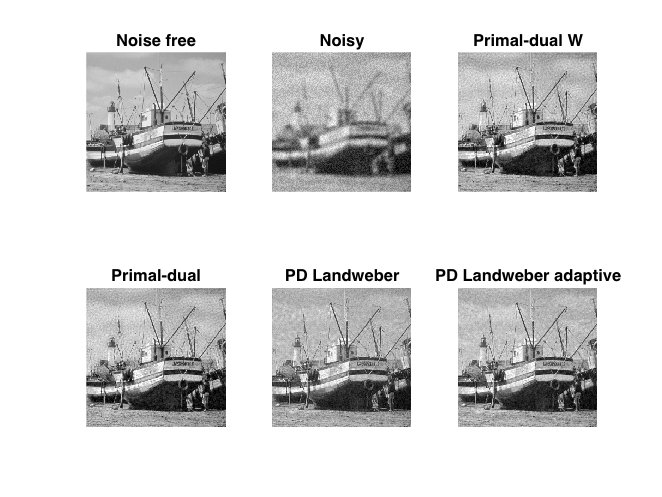

clf;
subplot(2,3,2)
imageplot(reshape(b_delta(1:M*N),M,N),'Noisy');
subplot(2,3,1)
imageplot(x0,'Noise free');
subplot(2,3,3)
imageplot(reshape(Image_PD(1:M*N),M,N),'Primal-dual W');
subplot(2,3,4)
imageplot(reshape(Image_PP(1:M*N),M,N),'Primal-dual');
subplot(2,3,6)
imageplot(reshape(Image_AL(1:M*N),M,N),'PD Landweber adaptive');
subplot(2,3,5)
imageplot(reshape(Image_L(1:M*N),M,N),'PD Landweber');